hw07

task 01

clear all;
da=load("hw\hw07\Exercise_7_data.mat");
data=da.data;
class=da.class;
f1=data(:,1);
h1 = chi2gof(f1)

h1 = 1

% as h1=1, so it's not Gaussian


task 02


c0_in=find(class==0);
d0_f1=f1(c0_in);
h0_1=chi2gof(d0_f1)

h0_1 = 1


AIC = zeros(1,10);
mc0_1 = cell(1,10);
options = statset('MaxIter',500);
for k = 1:10
    mc0_1{k} = fitgmdist(d0_f1,k,'Options',options,'CovarianceType','diagonal');
    AIC(k)= mc0_1{k}.AIC;
end
[minAIC,numComponents] = min(AIC);
BestModel1 = mc0_1{numComponents}

BestModel1 = 

在 1 个维中具有 2 个成分的高斯混合分布
成分 1:
混合比例: 0.511925
均值:    4.9498

成分 2:
混合比例: 0.488075
均值:    6.9674






c1_in=find(class==1);
d1_f1=f1(c1_in);
h1_1=chi2gof(d1_f1)

h1_1 = 0

AIC = zeros(1,10);
mc1_1 = cell(1,10);
options = statset('MaxIter',500);
for k = 1:10
    mc1_1{k} = fitgmdist(d1_f1,k,'Options',options,'CovarianceType','diagonal');
    AIC(k)= mc1_1{k}.AIC;
end
[minAIC,numComponents] = min(AIC);
BestModel2 = mc1_1{numComponents}

BestModel2 = 

在 1 个维中具有 2 个成分的高斯混合分布
成分 1:
混合比例: 0.564990
均值:   24.9817

成分 2:
混合比例: 0.435010
均值:   19.4644





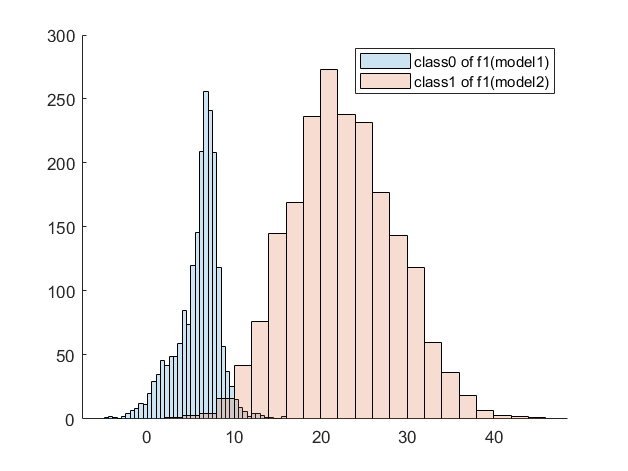


figure
hold on
h0_1=histogram(d0_f1);
h0_1.FaceAlpha=0.2;
h1_1=histogram(d1_f1);
h1_1.FaceAlpha=0.2;
legend("class0 of f1(model1)","class1 of f1(model2)")
hold off


syms x
eqn=@(x) BestModel1.pdf(x)-BestModel2.pdf(x)

eqn = 包含以下值的 function_handle :
    @(x)BestModel1.pdf(x)-BestModel2.pdf(x)


ran=[-10 100]

ran =    -10   100


x=fzero(eqn,ran)

x = 10.9492

error1=cdf(BestModel2,x);
error2=cdf(BestModel1,inf)-cdf(BestModel1,x);
error=error2+error1

error = 0.0334

task 03

% c0_in=find(class==0);
f2=data(:,2);
d0_f2=f2(c0_in);
h0_2=chi2gof(d0_f2)

h0_2 = 0


AIC = zeros(1,10);
mc0_2 = cell(1,10);
options = statset('MaxIter',500);
for k = 1:10
    mc0_2{k} = fitgmdist(d0_f2,k,'Options',options,'CovarianceType','diagonal');
    AIC(k)= mc0_2{k}.AIC;
end
[minAIC,numComponents] = min(AIC);
BestModel1 = mc0_2{numComponents}

BestModel1 = 

在 1 个维中具有 1 个成分的高斯混合分布
成分 1:
混合比例: 1.000000
均值:    9.9723






% c1_in=find(class==1);
d1_f2=f2(c1_in);
h1_2=chi2gof(d1_f2)

h1_2 = 0

AIC = zeros(1,10);
mc1_2 = cell(1,10);
options = statset('MaxIter',500);
for k = 1:10
    mc1_2{k} = fitgmdist(d1_f2,k,'Options',options,'CovarianceType','diagonal');
    AIC(k)= mc1_2{k}.AIC;
end
[minAIC,numComponents] = min(AIC);
BestModel2 = mc1_2{numComponents}

BestModel2 = 

在 1 个维中具有 1 个成分的高斯混合分布
成分 1:
混合比例: 1.000000
均值:   20.0277





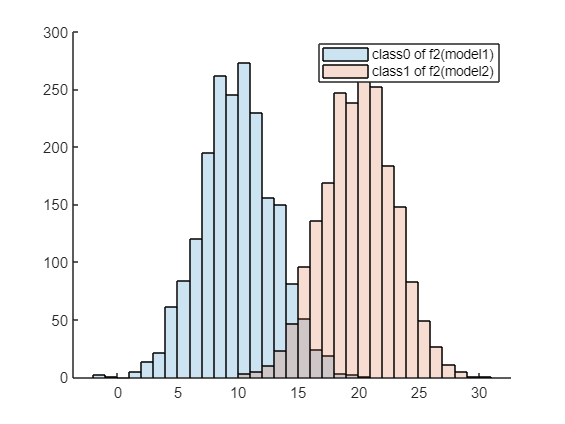


figure
hold on
h0_2=histogram(d0_f2);
h0_2.FaceAlpha=0.2;
h1_2=histogram(d1_f2);
h1_2.FaceAlpha=0.2;
legend("class0 of f2(model1)","class1 of f2(model2)")
hold off


syms x
eqn=@(x) BestModel1.pdf(x)-BestModel2.pdf(x)

eqn = 包含以下值的 function_handle :
    @(x)BestModel1.pdf(x)-BestModel2.pdf(x)


ran=[-10 100]

ran =    -10   100


x=fzero(eqn,ran)

x = 15.0196

error1=cdf(BestModel2,x);
error2=cdf(BestModel1,inf)-cdf(BestModel1,x);
error=error2+error1

error = 0.0937

task 04

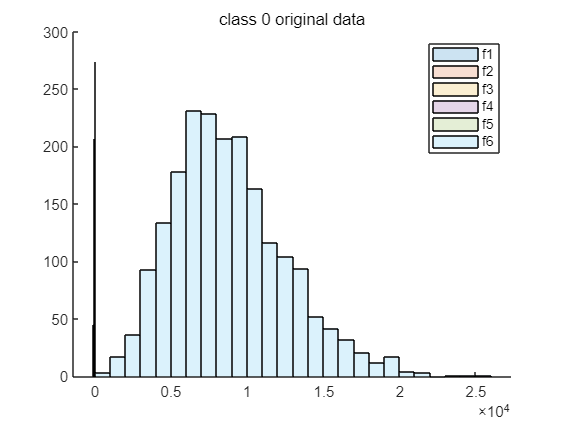

figure
hold on
h0_1=histogram(data(c0_in,1));
h0_1.FaceAlpha=0.2;
h0_2=histogram(data(c0_in,2));
h0_2.FaceAlpha=0.2;
h0_3=histogram(data(c0_in,3));
h0_3.FaceAlpha=0.2;
h0_4=histogram(data(c0_in,4));
h0_4.FaceAlpha=0.2;
h0_5=histogram(data(c0_in,5));
h0_5.FaceAlpha=0.2;
h0_6=histogram(data(c0_in,6));
h0_6.FaceAlpha=0.2;
legend("f1","f2","f3","f4","f5","f6")
title('class 0 original data')
hold off

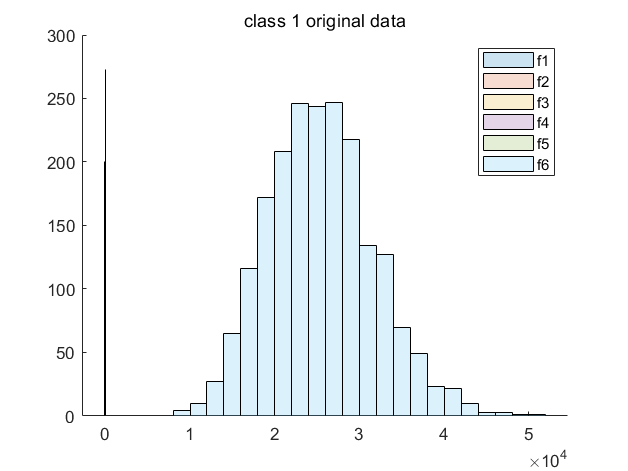


figure
hold on
h1_1=histogram(data(c1_in,1));
h1_1.FaceAlpha=0.2;
h1_2=histogram(data(c1_in,2));
h1_2.FaceAlpha=0.2;
h1_3=histogram(data(c1_in,3));
h1_3.FaceAlpha=0.2;
h1_4=histogram(data(c1_in,4));
h1_4.FaceAlpha=0.2;
h1_5=histogram(data(c1_in,5));
h1_5.FaceAlpha=0.2;
h1_6=histogram(data(c1_in,6));
h1_6.FaceAlpha=0.2;
legend("f1","f2","f3","f4","f5","f6")
title('class 1 original data')
hold off

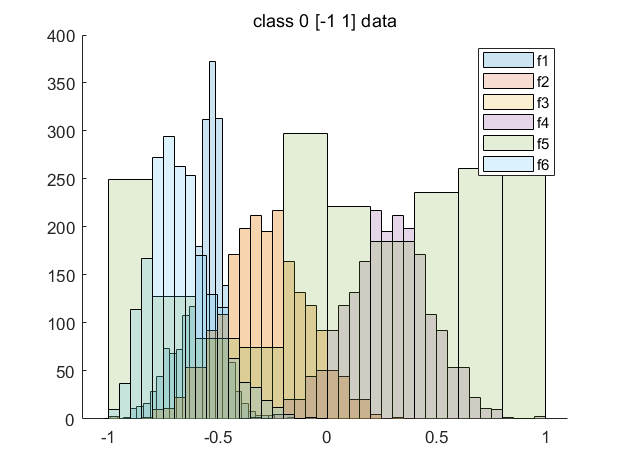


%normalization
normd=[];
for i=1:6
   low=min(data(:,i));
   up=max(data(:,i));
   fi=(data(:,i)-low)/(up-low)*2-1;
   normd=cat(2,normd,fi);
end 
figure
hold on
h0_1=histogram(normd(c0_in,1));
h0_1.FaceAlpha=0.2;
h0_2=histogram(normd(c0_in,2));
h0_2.FaceAlpha=0.2;
h0_3=histogram(normd(c0_in,3));
h0_3.FaceAlpha=0.2;
h0_4=histogram(normd(c0_in,4));
h0_4.FaceAlpha=0.2;
h0_5=histogram(normd(c0_in,5));
h0_5.FaceAlpha=0.2;
h0_6=histogram(normd(c0_in,6));
h0_6.FaceAlpha=0.2;
legend("f1","f2","f3","f4","f5","f6")
title('class 0 [-1 1] data')
hold off


%
p0=length(c0_in)/length(data);
p1=length(c1_in)/length(data);
d0=normd(c0_in,:);
d1=normd(c1_in,:);

AIC = zeros(1,10);
mc0 = cell(1,10);
options = statset('MaxIter',500);
for k = 1:10
    mc0{k} = fitgmdist(d0,k,'Options',options,'CovarianceType','diagonal');
    AIC(k)= mc0{k}.AIC;
end
[minAIC,numComponents] = min(AIC);
BestModel1 = mc0{numComponents};

AIC = zeros(1,10);
mc1 = cell(1,10);
options = statset('MaxIter',500);
for k = 1:10
    mc1{k} = fitgmdist(d1,k,'Options',options,'CovarianceType','diagonal');
    AIC(k)= mc1{k}.AIC;
end
[minAIC,numComponents] = min(AIC);
BestModel2 = mc1{numComponents};

p_w0=@(x) BestModel1.pdf(x)

p_w0 = 包含以下值的 function_handle :
    @(x)BestModel1.pdf(x)


p_w1=@(x) BestModel2.pdf(x)

p_w1 = 包含以下值的 function_handle :
    @(x)BestModel2.pdf(x)


y1=pdf(BestModel1,normd);
y2=pdf(BestModel2,normd);
ym=y1-y2;
ind=find(abs(ym)<=1);
datab=normd(ind,:);

low4=min(datab);
up4=max(datab);
equ=@(x) abs(BestModel1.pdf(x)-BestModel2.pdf(x));
ran4=[low4; up4];
x4=fminsearch(equ,[low4])

x4 =     0.4095   -1.0958   -1.1347   -2.0043   -0.9152   -1.9924


er1=cdf(BestModel1,x4);
er2=cdf(BestModel2,[inf inf inf inf inf inf])-cdf(BestModel2,x4);
er=er1+er2

er = 1.0000

task 05

ind=randperm(length(data));
for i=[1,2,3,4,5,6,7]
    ind0=randperm(length(data));
    ind=ind(ind0);
end
training_ind=ind(1:length(data)*0.3);
testing_ind=ind(1+length(data)*0.3:end);

ori=zeros(length(data),2);
ori(c0_in,1)=1;
ori(c1_in,2)=1;
te_d=normd(testing_ind,:);
te_l=class(testing_ind);

the_net=Ex4_NNsetup(normd,ori,training_ind,testing_ind)

the_net =

    Neural Network
 
              name: 'Pattern Recognition Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 2
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 92
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1]
      

prob=the_net(te_d');
[pob,I]=sort(prob,'descend');
indn=I(1,:);
di=(indn-1)-te_l;
corre=find(di==0);
accu=length(corre)/length(di)

accu = 0.9971

task 06

corr(data)

ans =     1.0000    0.7493    0.7493   -0.7493    0.0313    0.7423
    0.7493    1.0000    1.0000   -1.0000    0.0169    0.9893
    0.7493    1.0000    1.0000   -1.0000    0.0169    0.9893
   -0.7493   -1.0000   -1.0000    1.0000   -0.0169   -0.9893
    0.0313    0.0169    0.0169   -0.0169    1.0000    0.0178
    0.7423    0.9893    0.9893   -0.9893    0.0178    1.0000


corr(normd)

ans =     1.0000    0.7493    0.7493   -0.7493    0.0313    0.7423
    0.7493    1.0000    1.0000   -1.0000    0.0169    0.9893
    0.7493    1.0000    1.0000   -1.0000    0.0169    0.9893
   -0.7493   -1.0000   -1.0000    1.0000   -0.0169   -0.9893
    0.0313    0.0169    0.0169   -0.0169    1.0000    0.0178
    0.7423    0.9893    0.9893   -0.9893    0.0178    1.0000


%feature3 and feature2; feature3 and feature2 are not independent

task 07

% For linear correlation analysis, the linear correlation coefficient
% is used to measure the correlation and closeness of two variables.
% One of the biggest drawbacks of correlation-based feature selection
% is that it only detects linear relationships (relationships that can
% be fitted with a straight line). That is to say, we must first 
% confirm that the two variables are linearly related, and then the
% correlation coefficient can tell us how closely they are related,
% and vice versa. If the two variables themselves are linearly related,
% then the Pearson correlation coefficient is no problem. The larger 
% the absolute value is, the stronger the correlation is. But if we 
% don't know what the relationship is between these two variables, 
% even if we calculate the Pearson correlation coefficient and find
% that it is very large, it does not mean that the two variables are 
% linearly related, or even that they are related. We must draw a 
% picture to see it. For nonlinear relationships, mutual information 
% is more important. When doing feature selection, we should not focus
% on the type of data relationship (linear relationship), but consider
% how much information one feature can provide given another feature. 
% Mutual information formalizes the above reasoning engineering by 
% computing the information shared by the two features. Unlike 
% correlation, it depends not on the sequence of the data, but on 
% the distribution of the data. A nice property of mutual information 
% is that, unlike correlation, it doesn't just focus on linear relationships. 
% Features measurements assessed to be uncorrelated can still share 
% mutual information.

task 08

% In general, the less correlated the features, the better the classifier 
% performance. Correlated features by themselves do not affect 
% classification accuracy, but if two features are perfectly 
% correlated, no other useful information is added. The effect of 
% correlation depends on the type of classifier. Some nonparametric 
% classifiers are less sensitive to the correlation of variables. 
% High mutual information between multiple features allows some 
% categorical information to be repeated in more features. Since 
% we are computing more, it will weight these features more. If 
% there is mutual information, there are linear and non-linear 
% mappings between different features, and then we over-count the 
% amount of specific information.

task 09

% Data can be visualized using partial dependence plots (PDPs) to 
% see if features have nonlinear relationships. Comparing mutual 
% information or maximal information coefficient is also a judgment
% method. Another approach would be to first train a model and then 
% use the feature importance scores of this model. Feature importance 
% gives a measure of how much a particular feature has improved the 
% accuracy of a model.

function

%Template for setting up and training a pattern classification neural net
%which:
%1) performs no normalization or other preprocessing of the input
%2) uses predefined test/va/train sets according to indices
%
%-- A. Dimopoulos, June 2022

function NN=Ex4_NNsetup(data,label,trInd,teInd)
%all Data and labels. -->DEFINE THESE<--
Dall=data';
Tall=label';

%set indices. -->DEFINE THESE<--
%training indices
TRAIN_IND = trInd;
%validation indices
% pos=randi(length(teInd)/2);
VAL_IND = teInd(1:length(teInd)/5);
%testing indices
TEST_IND = teInd(length(teInd)/5+1:length(teInd));

%declare a classification network with default number of hidden units
n = patternnet;
%ensure that no data normalization or other preprocessing is performed
n.inputs{1}.processFcns = {};
%assign train/val/test sets by index
n.divideFcn = 'divideind';
n.divideParam.trainInd = TRAIN_IND;
n.divideParam.valInd = VAL_IND;
n.divideParam.testInd = TEST_IND;
%configure input and output sizes
n = configure(n,Dall,Tall);
%initialize the network weights
n = init(n);
%train the network
[n,train_record] = train(n,Dall,Tall,'useGPU','yes');
NN=n;
end